# ***BLOQUE 1 - HERRAMIENTA DE CONTROL***

# *Ejercicio 1 - Definición FDT*

G1 = tf([1], [1 0 1])                                  %Crea objeto tipo FDT

G1 =
 
     1
  -------
  s^2 + 1
 
Continuous-time transfer function.



G2 = tf([1 2 3],[1 0 4 0 5 6])

G2 =
 
      s^2 + 2 s + 3
  ---------------------
  s^5 + 4 s^3 + 5 s + 6
 
Continuous-time transfer function.



# *Ejercicio 2 - Multiplicación de polinomios*

G3 = tf([10 50], conv(conv([1 1],[1 3]),[1 3 6]))     %conv:producto vectorial

G3 =
 
             10 s + 50
  --------------------------------
  s^4 + 7 s^3 + 21 s^2 + 33 s + 18
 
Continuous-time transfer function.



# *Ejercicio 3 - Definición FDT mediante polos, cero y ganancia*

G4 = zpk([-1],[-2 -3 -4],[2])           %Escribe la FDT poniendo los ceros, polos y ganancia

G4 =
 
       2 (s+1)
  -----------------
  (s+2) (s+3) (s+4)
 
Continuous-time zero/pole/gain model.



G5 = zpk([],[-1 -1 -1],1)

G5 =
 
     1
  -------
  (s+1)^3
 
Continuous-time zero/pole/gain model.



G6 = zpk([],[-1 -1+2i -1-2i],[1])

G6 =
 
           1
  --------------------
  (s+1) (s^2 + 2s + 5)
 
Continuous-time zero/pole/gain model.



# *Ejercicio 4 - Factorización de FDT ya definida*

zpk(G2)                                           %Factoriza una FDT ya definida

ans =
 
                       (s^2 + 2s + 3)
  ---------------------------------------------------------
  (s+0.7738) (s^2 - 1.505s + 2.244) (s^2 + 0.7312s + 3.455)
 
Continuous-time zero/pole/gain model.



zpk(G3)                              

ans =
 
           10 (s+5)
  --------------------------
  (s+3) (s+1) (s^2 + 3s + 6)
 
Continuous-time zero/pole/gain model.



# *Ejercicio 5 - Definición de FDT de manera simbólica*

s = tf('s')                                     %Indica que s es FDT

s =
 
  s
 
Continuous-time transfer function.



G7 = (5*s^2+2*s-10)/((s+5)*(s+10)*s)

G7 =
 
   5 s^2 + 2 s - 10
  -------------------
  s^3 + 15 s^2 + 50 s
 
Continuous-time transfer function.



# *Ejercicio 10 - Álgebra de bloques*

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G8 = (2.5*(s+5))

G8 =
 
  2.5 s + 12.5
 
Continuous-time transfer function.



G9 = zpk([],[-0.5 -1],10)

G9 =
 
       10
  -------------
  (s+0.5) (s+1)
 
Continuous-time zero/pole/gain model.



H = 6

H = 6

feedback(series(G8,G9),H,-1)             %Importante indicar el signo de la realimentación

ans =
 
       25 (s+5)
  -------------------
  (s+5.127) (s+146.4)
 
Continuous-time zero/pole/gain model.



# ***BLOQUE 2 - MATEMÁTICAS SIMBÓLICAS***

# *Ejercicio 6 - Descomposición en fracciones simples*

syms x
G10 = (5*x^2+2*x-10)/((x+5)*(x+10)*x)

$$G10 = \frac{5\,x^{2}+2\,x-10}{x\,\left(x+5\right)\,\left(x+10\right)}$$

ilaplace(G10)

$$ans = \frac{47\,{\mathrm{e}}^{-10\,t}}{5}-\frac{21\,{\mathrm{e}}^{-5\,t}}{5}-\frac{1}{5}$$

[r1,p1,k1]=residue([6 22 18],[1 6 11 6])        %Descomposición Y1(s)

r1 =     3.0000
    2.0000
    1.0000


p1 =    -3.0000
   -2.0000
   -1.0000



k1 =

     []



[r2,p2,k2]=residue([2 25 95 110],[1 9 26 24])   %Descomposición Y2(s)

r2 =     1.0000
    4.0000
    2.0000


p2 =    -4.0000
   -3.0000
   -2.0000


k2 = 2

# *Ejercicio 7 - Cálculo de transformadas inversas de Laplace*

syms x
Y3 = (5)/((x+1)*(x+5))

$$Y3 = \frac{5}{\left(x+1\right)\,\left(x+5\right)}$$

ilaplace(Y3)

$$ans = \frac{5\,{\mathrm{e}}^{-t}}{4}-\frac{5\,{\mathrm{e}}^{-5\,t}}{4}$$

Y4 = (1)/(x^2+x+1)

$$Y4 = \frac{1}{x^{2}+x+1}$$

ilaplace(Y4)

$$ans = \frac{2\,\sqrt{3}\,{\mathrm{e}}^{-\frac{t}{2}}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}$$

ilaplace((1/x)*Y3)                          %Respuesta frente a un escalón unitario

$$ans = \frac{{\mathrm{e}}^{-5\,t}}{4}-\frac{5\,{\mathrm{e}}^{-t}}{4}+1$$

ilaplace((1/x)*Y4)                         %Respuesta frente a un escalón unitario

$$ans = 1-{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)+\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}\right)$$

ilaplace((1/x^2)*Y3)                       %Respuesta frente a una rampa

$$ans = t+\frac{5\,{\mathrm{e}}^{-t}}{4}-\frac{{\mathrm{e}}^{-5\,t}}{20}-\frac{6}{5}$$

ilaplace((1/x^2)*Y4)                       %Respuesta frente a una rampa

$$ans = t+{\mathrm{e}}^{-\frac{t}{2}}\,\left(\cos\left(\frac{\sqrt{3}\,t}{2}\right)-\frac{\sqrt{3}\,\sin\left(\frac{\sqrt{3}\,t}{2}\right)}{3}\right)-1$$

# *Ejercicio 8 - Cálculo de transformadas de Laplace*

syms t
y5 = laplace(exp(-2*t)*cos(t))

$$y5 = \frac{s+2}{{\left(s+2\right)}^{2}+1}$$

y6 = laplace(t^2*exp(-2*t)*sin(t))

$$y6 = \frac{2\,{\left(2\,s+4\right)}^{2}}{{\left({\left(s+2\right)}^{2}+1\right)}^{3}}-\frac{2}{{\left({\left(s+2\right)}^{2}+1\right)}^{2}}$$

# ***BLOQUE 3 - COMBINACIÓN DE MATEMÁTICAS SIMBÓLICAS CON HERRAMIENTA DE CONTROL***

# *Ejercicio de ejemplo*

syms x
Y7=54*(x+27)*(x^3+52*x^2+37*x+73)/(x*(x^4+872*x^3+473*x^2+89*x+65)*(x^2+79*x+36))

$$Y7 = \frac{\left(54\,x+1458\right)\,\left(x^{3}+52\,x^{2}+37\,x+73\right)}{x\,\left(x^{2}+79\,x+36\right)\,\left(x^{4}+872\,x^{3}+473\,x^{2}+89\,x+65\right)}$$

[num7, den7]=numden(Y7)                    %Extraer numerador y denominador

$$num7 = 54\,\left(x+27\right)\,\left(x^{3}+52\,x^{2}+37\,x+73\right)$$

$$den7 = x\,\left(x^{2}+79\,x+36\right)\,\left(x^{4}+872\,x^{3}+473\,x^{2}+89\,x+65\right)$$

num7=sym2poly(num7)                        %Vector coeficientes numerador

num7 =           54        4266       77814       57888      106434


den7=sym2poly(den7)                        %Vector coeficientes denominador

den7 =            1         951       69397       68848       24124        8339        2340           0


Y7tf=tf(num7, den7)    %Definicion en el dominio de la frecuencia utilizando los vectores de coeficientes

Y7tf =
 
            54 s^4 + 4266 s^3 + 77814 s^2 + 57888 s + 106434
  ---------------------------------------------------------------------
  s^7 + 951 s^6 + 69397 s^5 + 68848 s^4 + 24124 s^3 + 8339 s^2 + 2340 s
 
Continuous-time transfer function.



collect(Y7)                               %Comparo con Y7 simbolico

$$ans = \frac{54\,x^{4}+4266\,x^{3}+77814\,x^{2}+57888\,x+106434}{x^{7}+951\,x^{6}+69397\,x^{5}+68848\,x^{4}+24124\,x^{3}+8339\,x^{2}+2340\,x}$$

Gzpk=zpk(Y7tf)                            %Factorizacion de Y7 en Laplace

Gzpk =
 
               54 (s+51.31) (s+27) (s^2 + 0.6934s + 1.423)
  ---------------------------------------------------------------------
  s (s+871.5) (s+78.54) (s+0.5858) (s+0.4584) (s^2 - 0.04316s + 0.1273)
 
Continuous-time zero/pole/gain model.



factor(Y7)                                %Factorizacion de Y7 en simbolico

$$ans = \left(\begin{array}{cccccc} 54 & x+27 & x^{3}+52\,x^{2}+37\,x+73 & \frac{1}{x} & \frac{1}{x^{2}+79\,x+36} & \frac{1}{x^{4}+872\,x^{3}+473\,x^{2}+89\,x+65} \end{array}\right)$$

# *Ejercicio de ejemplo*

syms x;
Y8=zpk([1],[-2 3 -4],5)                   %Definicion FDT

Y8 =
 
       5 (s-1)
  -----------------
  (s+2) (s+4) (s-3)
 
Continuous-time zero/pole/gain model.



[num,den]=tfdata(Y8)                      %Coeficientes del numerador y del denominador

num = 1×1 cell array
    {[0 0 5 -5]}


den = 1×1 cell array
    {[1 3 -10 -24]}


num=cell2mat(num) %Cambio tipo cell array a tipo array, ya que poly2sym sólo acepta vectores

num =      0     0     5    -5


den=cell2mat(den)                        %Cambio tipo cell array a tipo array

den =      1     3   -10   -24


y8=poly2sym(num)/poly2sym(den)           %Def polinomio simbolico con los vectores de coeficientes

$$y8 = -\frac{5\,x-5}{-x^{3}-3\,x^{2}+10\,x+24}$$

# ***BLOQUE 4 - ESTUDIO DE LA RESPUESTA TRANSITORIA DE SISTEMAS DE CONTROL***

# *Ejercicio 9*

P1 = zpk([-1],[1 -2 -4],[1])             %Definicion polinomio, ganancia 1

P1 =
 
        (s+1)
  -----------------
  (s-1) (s+2) (s+4)
 
Continuous-time zero/pole/gain model.



Polosp1 = pole(P1)                       %Obtiene los polos del polinomio

Polosp1 =      1
    -2
    -4


Cerosp1 = zero(P1)                       %Obtiene los ceros del polinomio

Cerosp1 = -1

P1Z = feedback(P1,1,-1)                  %Importante indicar el signo de la realimentación

P1Z =
 
              (s+1)
  ------------------------------
  (s-0.8662) (s+2.211) (s+3.655)
 
Continuous-time zero/pole/gain model.



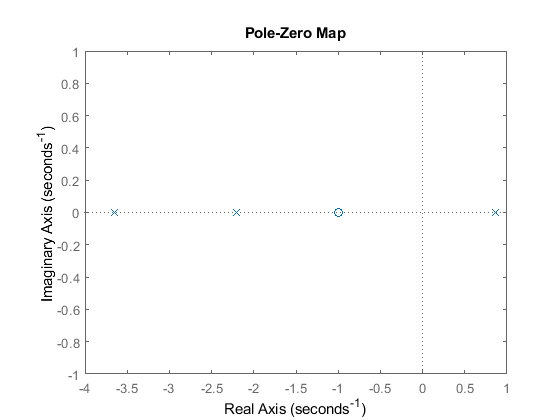

pzmap(P1Z)                               %Abre el mapa de polos y ceros del sistema

P2 = zpk([-1],[1 -2 -4],[3])             %Definicion polinomio, ganancia 3

P2 =
 
       3 (s+1)
  -----------------
  (s-1) (s+2) (s+4)
 
Continuous-time zero/pole/gain model.



P2Z = feedback(P2,1,-1)

P2Z =
 
               3 (s+1)
  ---------------------------------
  (s-0.5987) (s^2 + 5.599s + 8.352)
 
Continuous-time zero/pole/gain model.



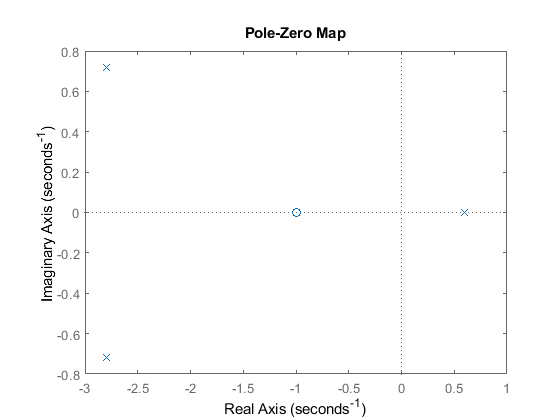

pzmap(P2Z)

P3 = zpk([-1],[1 -2 -4],[10])            %Definicion polinomio, ganancia 10

P3 =
 
      10 (s+1)
  -----------------
  (s-1) (s+2) (s+4)
 
Continuous-time zero/pole/gain model.



P3Z = feedback(P3,1,-1)

P3Z =
 
              10 (s+1)
  --------------------------------
  (s+0.1796) (s^2 + 4.82s + 11.13)
 
Continuous-time zero/pole/gain model.



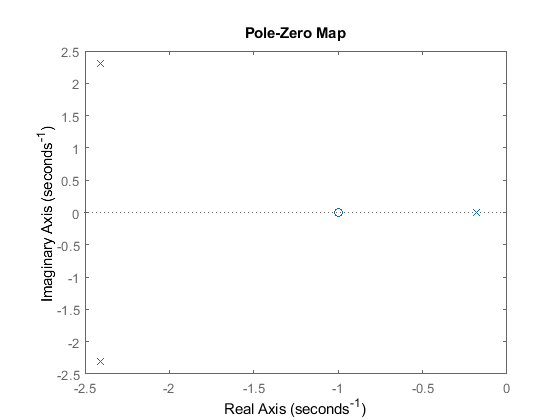

pzmap(P3Z)

# *Ejercicio 10*

polos10 = [-0.5 -1 -3 -5 -10];
for t=1:length(polos10)
    G_10(t) = zpk([],[polos10(t)],-polos10(t))   %La ganancia es el valor de (a = - el polo) para que la salida siempre sea 1
end

G_10 =
 
    0.5
  -------
  (s+0.5)
 
Continuous-time zero/pole/gain model.


G_10 =
 
  From input 1 to output:
    0.5
  -------
  (s+0.5)
 
  From input 2 to output:
    1
  -----
  (s+1)
 
Continuous-time zero/pole/gain model.


G_10 =
 
  From input 1 to output:
    0.5
  -------
  (s+0.5)
 
  From input 2 to output:
    1
  -----
  (s+1)
 
  From input 3 to output:
    3
  -----
  (s+3)
 
Continuous-time zero/pole/gain model.


G_10 =
 
  From input 1 to output:
    0.5
  -------
  (s+0.5)
 
  From input 2 to output:
    1
  -----
  (s+1)
 
  From input 3 to output:
    3
  -----
  (s+3)
 
  From input 4 to output:
    5
  -----
  (s+5)
 
Continuous-time zero/pole/gain model.


G_10 =
 
  From input 1 to output:
    0.5
  -------
  (s+0.5)
 
  From input 2 to output:
    1
  -----
  (s+1)
 
  From input 3 to output:
    3
  -----
  (s+3)
 
  From input 4 to output:
    5
  -----
  (s+5)
 
  From input 5 to output:
    10
  ------
  (s+10)
 
Continuous-time zero/pole/gain model.


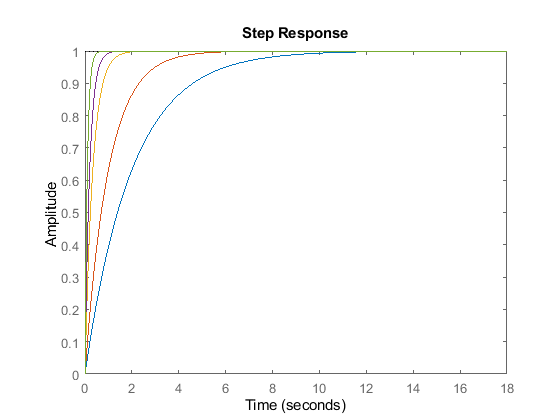

figure; hold on                               %Dibuja en la misma grafica todas las respuestas
step(G_10(1),G_10(2),G_10(3),G_10(4),G_10(5))

# *Ejercicio 11*

K = 1; Wn = 2;                             %Ganancia 1, frecuencia natural 2
chi = [0 0.25 1 5];                        %Coeficientes de amortiguamiento
for t=1:length(chi)
    G_11(t) = tf([K*Wn^2],[1 2*chi(t)*Wn Wn^2]) %La ganancia es el valor de (a = - el polo) para que la salida siempre sea 1
end

G_11 =
 
     4
  -------
  s^2 + 4
 
Continuous-time transfer function.


G_11 =
 
  From input 1 to output:
     4
  -------
  s^2 + 4
 
  From input 2 to output:
       4
  -----------
  s^2 + s + 4
 
Continuous-time transfer function.


G_11 =
 
  From input 1 to output:
     4
  -------
  s^2 + 4
 
  From input 2 to output:
       4
  -----------
  s^2 + s + 4
 
  From input 3 to output:
        4
  -------------
  s^2 + 4 s + 4
 
Continuous-time transfer function.


G_11 =
 
  From input 1 to output:
     4
  -------
  s^2 + 4
 
  From input 2 to output:
       4
  -----------
  s^2 + s + 4
 
  From input 3 to output:
        4
  -------------
  s^2 + 4 s + 4
 
  From input 4 to output:
        4
  --------------
  s^2 + 20 s + 4
 
Continuous-time transfer function.



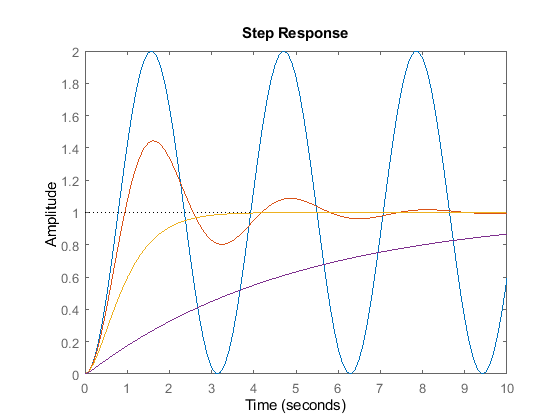

figure; hold on                            %Dibuja en la misma grafica todas las respuestas
step(G_11(1),G_11(2),G_11(3),G_11(4),10)

# *Ejercicios 12 y 13*

clear
iter = 1;
a = 1;
tr = 1;
while tr>0.001
    A = stepinfo(zpk([],[-a],1));
    tr = A.RiseTime;
    iter = iter + 1;
    a=a+50;
    if iter > 5000
        break
    end
end
a

a = 2251

iter

iter = 46